

% Lamina  12
syms x y z
v1 = [2 -1 4]'

v1 =      2
    -1
     4


v2 = [ 4 1 6]'

v2 =      4
     1
     6


A= [v1 v2]

A =      2     4
    -1     1
     4     6


X= [x y z]'

$$X = \left(\begin{array}{c} \bar{x}\\ \bar{y}\\ \bar{z} \end{array}\right)$$

Au = [A X]

$$Au = \left(\begin{array}{ccc} 2 & 4 & \bar{x}\\ -1 & 1 & \bar{y}\\ 4 & 6 & \bar{z} \end{array}\right)$$

rref(Au)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$



% Lamina 13
% Definición de los vectores v1, v2 y v3
v1 = [1; -1; 2];
v2 = [2; 3; 0];
v3 = [-1; -9; 6];

% Forma los siguientes sisetem Ax=b donde A=[v_1 v_2] b=v_3 y permuta. 
% Esto se hace par saber si uno de los vectores es combinación lineal
% de los otros dos.



% Luego piensa como usar la matriz A = A=[v_1 v_2 v_3]







% Lamina 14
% Definición de los vectores v1, v2 y v3
v1 = [1; 1; 0];
v2 = [0; 1; 1];
v3 = [1; 0; 1];

% Creación de la matriz A con los vectores como columnas
A = [v1, v2, v3];
disp('Matriz A:');

Matriz A:


disp(A);

     1     0     1
     1     1     0
     0     1     1






% Lamina 15
% Definición de los vectores v1, v2, v3 y v4
v1 = [1; 1; 0];
v2 = [2; 1; -1];
v3 = [-1; 1; 2];
v4 = [0; 1; 1];

% Creación de la matriz A con los vectores como columnas
A = [v1, v2, v3, v4];
disp('Matriz A:');

Matriz A:


disp(A);

     1     2    -1     0
     1     1     1     1
     0    -1     2     1





%Lámina 16
% Definición de los vectores v1, v2 y v3
v1 = [1; 2; 5];
v2 = [-2; -4; -9];
v3 = [0; 1; 1];

% Creación de la matriz A con los vectores como columnas
A = [v1, v2, v3];
disp('Matriz A:');

Matriz A:


disp(A);

     1    -2     0
     2    -4     1
     5    -9     1



# Ejemplo 1

% Determine si el vector v es C.L de los vectores aleatorios u1,u2,u3.
v = [1; 5; 3; 5];
u1 = randi(10,4,1);
u2 = randi(20,4,1);
u3 = randi(30,4,1);
%%%% SOLUCION
A = [u1 u2 u3];
Aa = [A v];
if rank(A) == rank(Aa)
    fprintf("v es C.L de u1, u2, u3.")
else
    fprintf("v no es C.L de u1, u2, u3.")
end

v no es C.L de u1, u2, u3.

# Ejemplo 2

% Determine los coeficientes que se obtienen al escribir v como C.L de los vectores u1,u2,u3,u4.
v = [1; 5; 3; 5];
u1 = [0.5; 0; 0; 0];
u2 = [0; 0; 0; 3];
u3 = [0; -2; 0; 0];
u4 = [0; 0; -1; 0];
%%%% SOLUCION
A = [u1 u2 u3 u4];
if rank(A) == rank([A v]) && rank(A) == size(A,2)
    x = A\v;
    fprintf("Los pesos son %d, %d, %d, %d",x)
elseif rank(A) == rank([A v])
    fprintf("Hay infinitos valores para los coeficientes")
else 
    fprintf("v no es C.L de u1, u2, u3, u4")
end

Los pesos son 2, 1.666667e+00, -2.500000e+00, -3

# Ejemplo 3

% Determine si los siguientes vectores son linealmente independientes.
u1 = [0.5; 0.7; 0; 0];
u2 = [0; 2; 0; 3];
u3 = [0; -4; 9; 0];
%%%% SOLUCION
A = [u1 u2 u3];
if rank(A) == size(A,2) 
    fprintf("Los vectores u1, u2, u3 son LINEALMENTE INDEPENDIENTES")
else
    fprintf("Los vectores u1, u2, u3 son LINEALMENTE DEPENDIENTES")
end

Los vectores u1, u2, u3 son LINEALMENTE INDEPENDIENTES

# Encontrando la base de espacios generados

%%%% SOLUCION
u1 = [1 -4 3 5 0]';
u2 = [5 14 14 3.5 2]';
u3 = [0 2 7 1 1]';
u4 = [1 2 0 0.3 0]';
A = [u1 u2 u3 u4];
[R,p] = rref(A);
V = A(:,p) % Matriz cuyas columnas forman la base de Gen{u1,..,ur}

V =     1.0000    5.0000         0
   -4.0000   14.0000    2.0000
    3.0000   14.0000    7.0000
    5.0000    3.5000    1.0000
         0    2.0000    1.0000


# Motivación

Usa la IA para resolver este problema. Identifica los conceptos usados

Prompt

“Una compañía de concreto almacena tres mezclas básicas, que se presentan a continuación. Las cantidades se miden en gramos y cada ‘unidad’ de mezcla pesa 60 gramos. Puede formular mezclas especiales revolviendo combinaciones de las tres mezclas básicas; entonces las mezclas especiales posibles pertenecen al espacio generado por los tres vectores que representan a las tres mezclas básicas. 

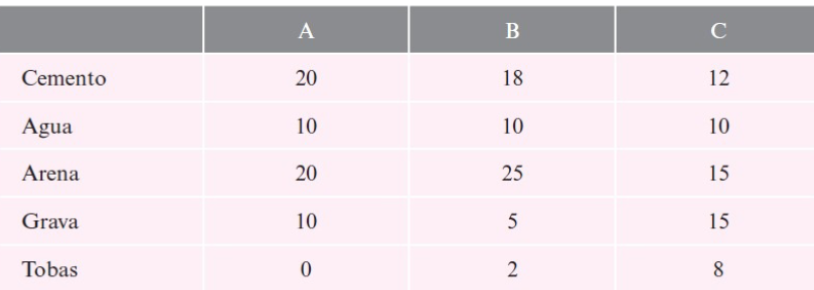

% Definición de la matriz con los valores de las mezclas
% Las filas representan respectivamente: Cemento, Agua, Arena, Brava y
% Tobas. Las columnas representan las tres diferentes tipos de mezcla A, B
% y C
matrix = [20 18 12; 10 10 10; 20 25 15; 10 5 15; 0 2 8];
 

a) ¿Se puede hacer una mezcla que consiste en 100 g de cemento, 200 g de agua, (100 g) de arena, (500 g) de grava y (300 g) de tobas? ¿Por qué sí o por qué no? De ser posible, ¿cuántas unidades de cada una de las mezclas A, B y C se necesitan para formular la mezcla especial?

Compara el resutlado entre 3 IAs diferentes. Gemeni, ChatGPT4. Copilot

b) Suponga que desea preparar (5000 g) de concreto con una razón de agua a cemento de 2 a 3 con (1250 g) de cemento. Si debe incluir (1500 g) de arena y (1000 g) de grava en las especificaciones, encuentre la cantidad de tobas para hacer (5000 g) de concreto. ¿Se puede formular esta como una mezcla especial? De ser así, ¿cuántas unidades de cada mezcla se necesitan para formular la mezcla especial?

#  Pregunta a la IA

¿Como se relaciona esto con el tema de combinación lineal es espacios vectoriales?